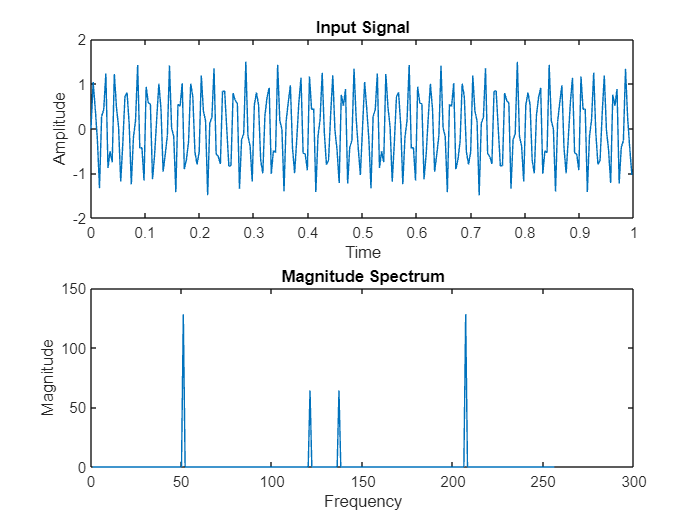

% Test function
N = 256; % Number of sample points
dt = 1/N;
t = 0:dt:1-dt; % time
x = sin(2*pi*50*t) + 0.5*sin(2*pi*120*t); % signal
y = fftx(x); % compute fft from naive recursion below

% Plot
subplot(2, 1, 1);
plot(t, x);
title('Input Signal');
xlabel('Time'); ylabel('Amplitude');

subplot(2, 1, 2);
plot(abs(y));
title('Magnitude Spectrum');
xlabel('Frequency'); ylabel('Magnitude');

function y = fftx(x)
N = length(x);
if N <= 1   % Compute Directly if N = 1
    y = x;
else
    % recursively compute FFT 
    even = fftx(x(1:2:N));
    odd = fftx(x(2:2:N));
    
    % combine
    factor = exp(-2i*pi*(0:N/2-1)/N);
    combined = factor .* odd;
    y = [even + combined , even - combined];
end
end